# Phase plane behaviour of state-space models in MATLAB

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state-space model. 

This file focuses on how to infer the expected open-loop behaviour of a state-space models, within the phase plane, that is the behaviour of the states rather than the inputs and the outputs. It is interesting to note how this behaviour can be linked to the eigenvalue/vector decomposition of the state matrix. it is also worth being familiar with the preceding files of:  ***statespace_models_from_tf_control101, tf_models_from_statespace_control101***.

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

The last section us a subfunction used to create the phase plots; users can copy this to a script file if they want to use elsewhere.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, Ross Drummond, Lanlan Su  (University of Sheffield) and Ruth Bars (Budapest University of Technology and Economics)                           

## Table of Contents

- Background on state transition matrix

- Analysing the state transitions and the phase plane

- Systems with complex poles

- Useful subfunction

## 1. Background on state transition matrix

The interest here is primarily on exploring the behaviour of the following system.

$\dot{x} =A\;x\;$with state x.

The impact of inputs on the behaviour is less interesting and left to private study.

One can solve for *x(t)* using a number of different methods and indeed use MATLAB to validate that these all give the same answer.

a) Using Laplace transforms: 


$$X\left(s\right)={\left\lbrack s\;I-A\right\rbrack }^{-1} x\left(0\right)\;\Rightarrow \;x\left(t\right)=L^{-1} {\left\lbrack s\;I-A\right\rbrack }^{-1} x\left(0\right)=\phi \left(t\right)x\left(0\right)$$
 

where $\phi \left(t\right)$ is the state transition matrix.

b) Solving the differential equation directly, using properties of matrices:


$$x\left(t\right)=e^{A\;t} x\left(0\right)\;\;\;\Rightarrow \;\;\phi \left(t\right)=e^{A\;t}$$


c) Using the eigenvalue/vector decomposition that $A=W\Sigma V$ where $\Sigma \;$is the diagonal matrix of eigenvalues and $W$ the matrix of eigenvectors  then:


$$x\left(t\right)=We^{\Sigma t} V\;x\left(0\right)\;\;\;\Rightarrow \;\;\phi \left(t\right)={\textrm{We}}^{\Sigma t} V$$


One can easily validate that all of these methods lead to the same state transition matrix (note with more complicated numbers the display is messy as seen in the 2nd example below, but will still work).

% system 1
W=[1 0;1 1]; Sigma = [-1 0;0 -2];
A=W*Sigma*inv(W);

[w,l]=eig(A); v=inv(w);
syms s t;
G=(inv(s*eye(2)-A));
Phit = ilaplace(G)

$$Phit = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & 0\\ {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-2\,t} \end{array}\right)$$

Phit_alternate2 = expm(A*t)

$$Phit\_alternate2 = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & 0\\ {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-2\,t} \end{array}\right)$$

Phit_alternate3 = w*expm(l*t)*v

$$Phit\_alternate3 = \left(\begin{array}{cc} {\mathrm{e}}^{-t} & 0\\ {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-2\,t} \end{array}\right)$$


% system 2
W=[1 0 0.1;1 1 1;2 -1 -3]; Sigma = [-1 0 0;0 -2 0; 0 0 -4];
A=W*Sigma*inv(W);
[w,l]=eig(A); v=inv(w);
syms s t;
G=(inv(s*eye(3)-A));
Phit = ilaplace(G);
Phit_alternate2 = expm(A*t);
Phit_alternate3 = w*expm(l*t)*v; 
disp('Compare at a specific value of t')

Compare at a specific value of t


[Phit_Phit2_Phit3]=eval([subs(Phit,1.2),subs(Phit_alternate2,1.2),subs(Phit_alternate3,1.2)])

Phit_Phit2_Phit3 =     0.2630    0.0127    0.0127    0.2630    0.0127    0.0127    0.2630    0.0127    0.0127
    0.0754    0.1357    0.0450    0.0754    0.1357    0.0450    0.0754    0.1357    0.0450
    0.6888   -0.0893    0.0014    0.6888   -0.0893    0.0014    0.6888   -0.0893    0.0014


**Remark**: Discrete examples can be handled with very similar code but noting that the state transition is:


$$x\left(k+1\right)=\phi x\left(k\right)$$


where, for sample time *T*, the appropriate matrices are:


$$\phi =e^{A\;T}$$


**Remark**: If the reader is only interested in step responses, that is the output from the system $\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y, *then details of how to produce these are summarised in the existing file: ***step_responses_with_matlab***  or ***openloop_behaviour_statespace_control101***. Simply create a system object using ***ss.m (see statespace_models_control101)***, and use this in place of the transfer function.

## 2. Analysing the state transitions and the phase plane

The interest here is on understanding the state trajectories and exploiting the information in the state transition matrix.


$$x\left(t\right)=We^{\Sigma t} V\;x\left(0\right)\;\;\;\Rightarrow \;\;\phi \left(t\right)={\textrm{We}}^{\Sigma t} V$$


Given the solution is expressed in terms of eigenvalues and eigenvectors, what insight does this give us. A decomposition shows the following.


$$x\left(t\right)=\sum_i w_i e^{\lambda_i t} v_i^T x\left(0\right)=\sum_i w_i e^{\lambda_i t} \left({\;v}_i^T x\left(0\right)\right);\;{\;\;\;\;\;\;\alpha }_i ={\;\;v}_i^T x\left(0\right)$$


So the response can be decomposed into a decay along each eigenvector direction. It is not the purpose of this note to derive this slowly, but rather to show how easily MATLAB tools can illustrate this behaviour and the insight it gives. A number of examples are given next. The circles and crosses are computed at equi-spaced time intervals (see ***phaseplot.m***) for convenience of illustration.

- It is seen that the state  (red circle) gradually moves towards the eigenvector direction $w_i \;$ associated to the slowest mode. 

- The red crosses show the contribution along each eigenvector direction for specific times, that is: $w_i \left\lbrack {\;e}^{\lambda_i t} \left({\;v}_i^T x\left(0\right)\right)\right\rbrack$.

- The times used for the '+' are arbitrary as these plots are illustrative of behaviours.

disp('BELOW is Example 1')

BELOW is Example 1


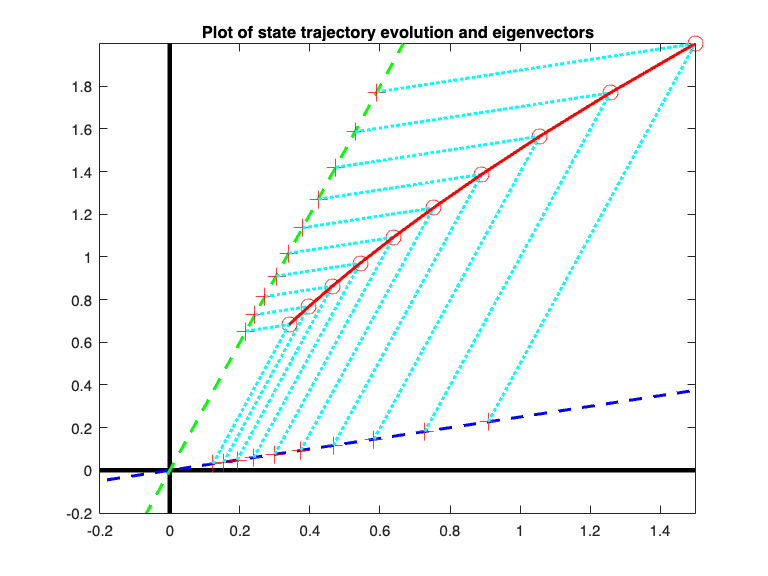

W=[1 4;3 1];
V=inv(W);
lambda=diag([-1 -2]);
A=W*lambda*V;

x0=[1.5;2];
phaseplot(A,x0,10)
axis([-.2,1.5,-0.2,2])
title('Plot of state trajectory evolution and eigenvectors')

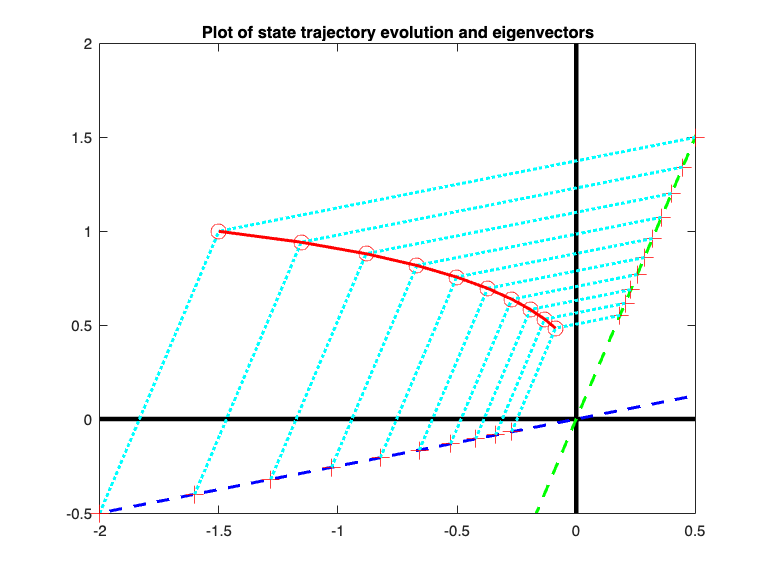


x0=[-1.5;1];
phaseplot(A,x0,10)
axis([-2,0.5,-0.5,2])
title('Plot of state trajectory evolution and eigenvectors')

disp('BELOW is Example 2')

BELOW is Example 2



W=[-1 4;2 1];
V=inv(W);
lambda=diag([-0.4 -2]);
A=W*lambda*V

A =    -1.8222   -0.7111
   -0.3556   -0.5778


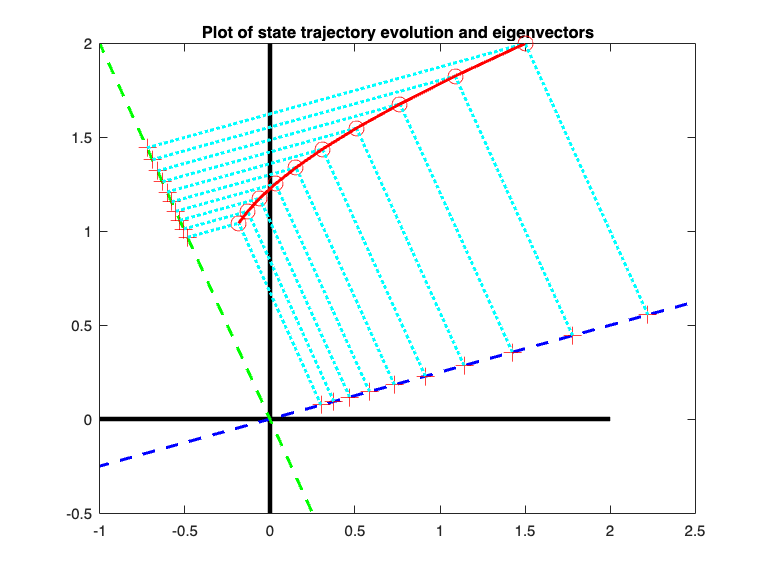


x0=[1.5;2];
phaseplot(A,x0,10)
axis([-1,2.5,-0.5,2])
title('Plot of state trajectory evolution and eigenvectors')

Example 3 shows how, where there are unstable modes, eventually the state will go to  the direction associated to that unstable mode.

disp('BELOW is Example 3')

BELOW is Example 3


W=[-1 4;2 1];
V=inv(W);
lambda=diag([0.4 -2]);
A=W*lambda*V

A =    -1.7333   -1.0667
   -0.5333    0.1333


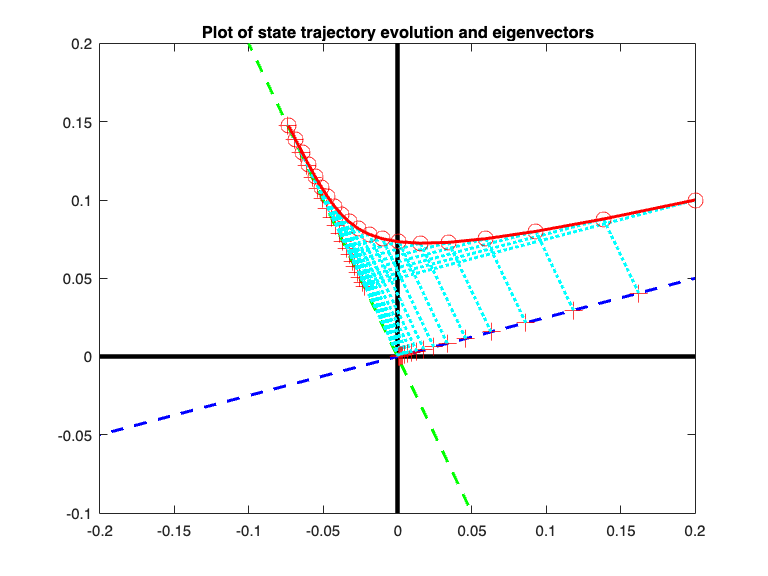


x0=[.2;.1];
phaseplot(A,x0,20)
axis([-0.2,0.2,-0.1,0.2])
title('Plot of state trajectory evolution and eigenvectors')

**Remark**: Discrete examples can be handled with very similar code but noting that the state transition is:


$$x\left(k+1\right)=\phi x\left(k\right)$$


## 3. Systems with complex poles

Again, it is not the purpose of this note to act as a text book, but rather to illustrate how easily informative plots can be produced of state behaviour. In the case where a state matrix has complex eigenvalues, then the associated behaviour is oscillatory. In the phase plane this will lead to spiral like behaviour which is easy to illustrate as in the following examples. First compute the state evolution x(t) and then simply plot for given values of time. 

This illustration is restricted to 2 state examples, but MATLAB could also illustrate 3-state examples with very similar code.

disp('BELOW is Example 4')

BELOW is Example 4


A=[0 0.1;-4 -0.04];
eigenvalues=eig(A)

eigenvalues =   -0.0200 + 0.6321i
  -0.0200 - 0.6321i


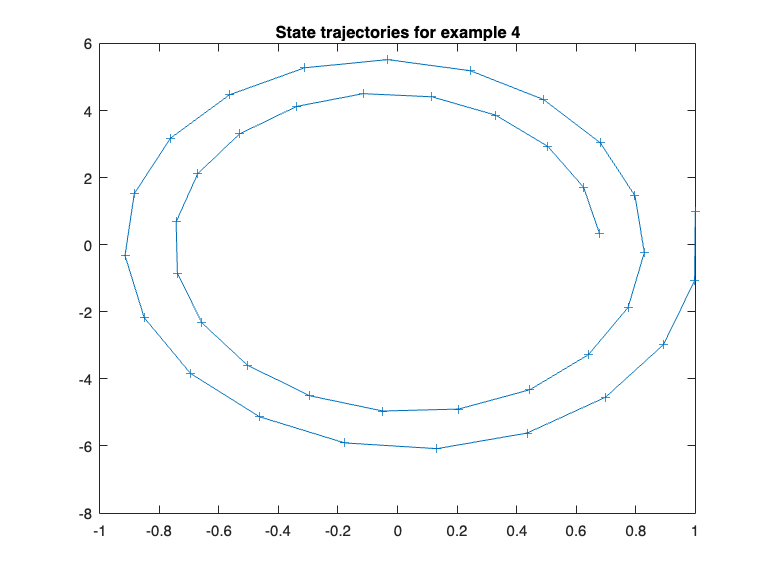

t=linspace(0,20,40);
x0=[1;1];
x=zeros(2,40);
for k=1:40
    x(:,k)=expm(A*t(k))*x0; 
end
plot(x(1,:),x(2,:),'+-')
title('State trajectories for example 4')


disp('BELOW is Example 5')

BELOW is Example 5


A=[0 0.1;-1 -0.2];
eigenvalues = eig(A)

eigenvalues =   -0.1000 + 0.3000i
  -0.1000 - 0.3000i


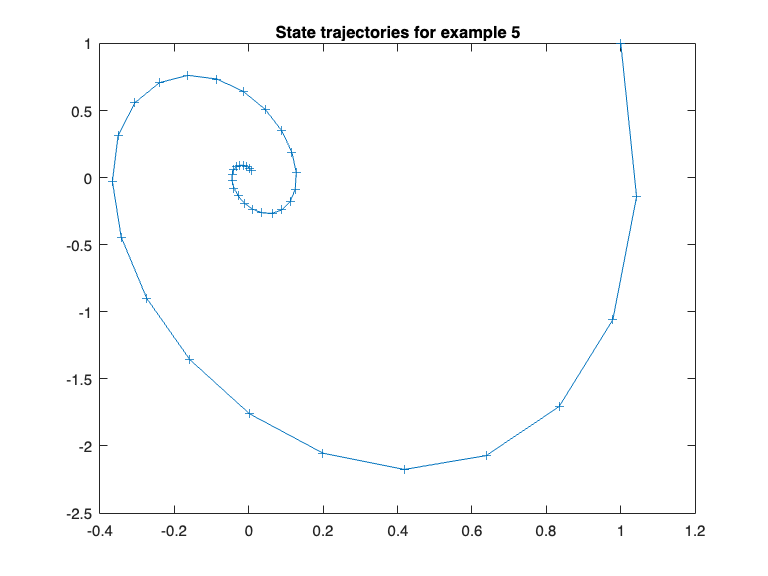

t=linspace(0,40,40);
x0=[1;1];
for k=1:40
    x(:,k)=expm(A*t(k))*x0; 
end
plot(x(1,:),x(2,:),'+-')
title('State trajectories for example 5')

## 4. Useful subfunction

The last section is a subfunction used to create the phase plots; users can copy this to a script file if they want to use elsewhere. This subfunction will produce phase plane plots for 2 state systems with real eigenvalues.

function phaseplot(A,x0,nsteps)

[w,l]=eig(A); v=inv(w); 


plot([-2 2],[0 0],'k','linewidth',3);
hold on
plot([0 0],[-2 2],'k','linewidth',3);
plot(10*w(1,1)*[1 -1],10*w(2,1)*[1 -1],'b--','linewidth',2);
plot(10*w(1,2)*[1 -1],10*w(2,2)*[1 -1],'g--','linewidth',2);
plot(1.5,2,'ro','markersize',10);
a1=v(1,:)*x0;
a2=v(2,:)*x0;
W1=w(:,1)*a1;
W2=w(:,2)*a2;
plot(W1(1),W1(2),'r+','markersize',12);
plot(W2(1),W2(2),'r+','markersize',12);
plot([W1(1),x0(1)],[W1(2),x0(2)],'c:','linewidth',2)
plot([W2(1),x0(1)],[W2(2),x0(2)],'c:','linewidth',2)

%add more time instants
tt=linspace(0,0.2*nsteps-1,nsteps);
lam1t=exp(l(1,1)*tt);
lam2t=exp(l(2,2)*tt);
W1=W1*lam1t;W2=W2*lam2t;

for k=1:nsteps;
    X0(:,k)=expm(A*tt(k))*x0;
    plot(X0(1,k),X0(2,k),'ro','markersize',10);
    plot(W1(1,k),W1(2,k),'r+','markersize',12);
plot(W2(1,k),W2(2,k),'r+','markersize',12);
plot([W1(1,k),X0(1,k)],[W1(2,k),X0(2,k)],'c:','linewidth',2)
plot([W2(1,k),X0(1,k)],[W2(2,k),X0(2,k)],'c:','linewidth',2)

end

plot(X0(1,:),X0(2,:),'r-','linewidth',2)
hold off

end    